ng_value = 0;
flux_value = .125;
kappa_tot = 1.5; % MHz
kerr = find_kerr_MHz_ng_flux(ng_value, flux_value);
detunings = linspace(-40, 40, 1000);
flux_power_at_room_temp_dBm = linspace(-10, 25, 200);

[eta_values_MHz, flux_amp_at_sample_in_quanta] = find_eta_MHz_ng_flux(ng_value, ...
    flux_value, flux_power_at_room_temp_dBm);
[delta_mesh, eta_mesh] = meshgrid(detunings, eta_values_MHz);
[~, flux_power_mesh_dBm] = meshgrid(detunings, flux_power_at_room_temp_dBm);

Based on the notes - where we define $\Delta$ = $\omega_0 - \frac{\omega_p}{3}$, whereas in the data collection codes it is defined as $\Delta = \frac{\omega_p}{3} - \omega_0$

number_photons_soln_1 = ((-2*kerr*delta_mesh + abs(eta_mesh).^2) - ...
    sqrt(abs(eta_mesh).^4 - 4*kerr*delta_mesh.*abs(eta_mesh).^2 - kerr^2*kappa_tot^2))/2/kerr^2;
number_photons_soln_2 = ((-2*kerr*delta_mesh + abs(eta_mesh).^2) + ...
    sqrt(abs(eta_mesh).^4 - 4*kerr*delta_mesh.*abs(eta_mesh).^2 - kerr^2*kappa_tot^2))/2/kerr^2;

number_photons_soln_1(imag(number_photons_soln_1) ~= 0) = 0;
number_photons_soln_1(number_photons_soln_1 < 0) = 0;
number_photons_soln_2(imag(number_photons_soln_2) ~= 0) = 0;
number_photons_soln_2(number_photons_soln_2 < 0) = 0;

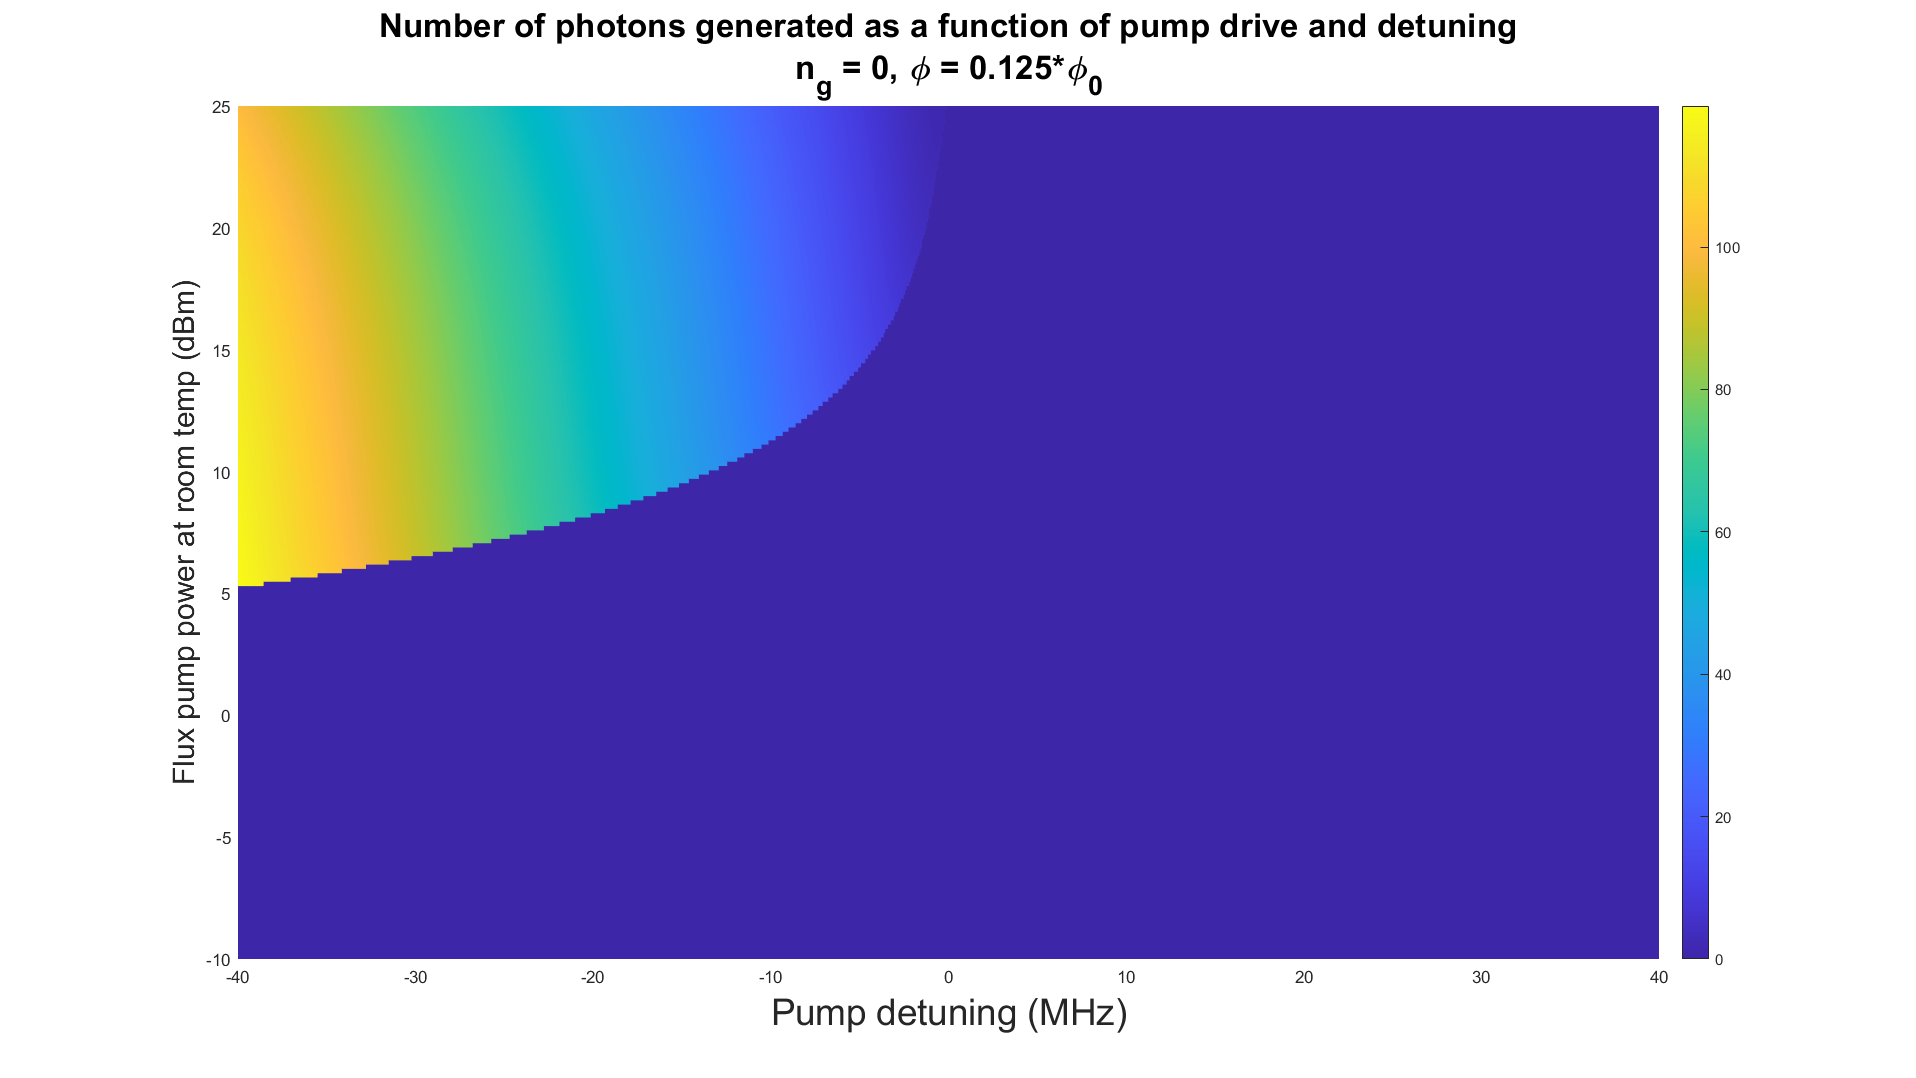

fig = figure('Name','test','NumberTitle','off','units','normalized','outerposition',[0 0 1 1]);    
surf(-delta_mesh, flux_power_mesh_dBm, number_photons_soln_1, 'Linestyle', 'none')
title(['Number of photons generated as a function of pump drive and detuning' ...
13 10 'n_g = ' num2str(ng_value) ', \phi = ' num2str(flux_value) '*\phi_0'], 'FontSize', 20)
xlabel('Pump detuning (MHz)','FontSize',22)
ylabel('Flux pump power at room temp (dBm)', 'Fontsize', 18)
view(0,90)
colorbar

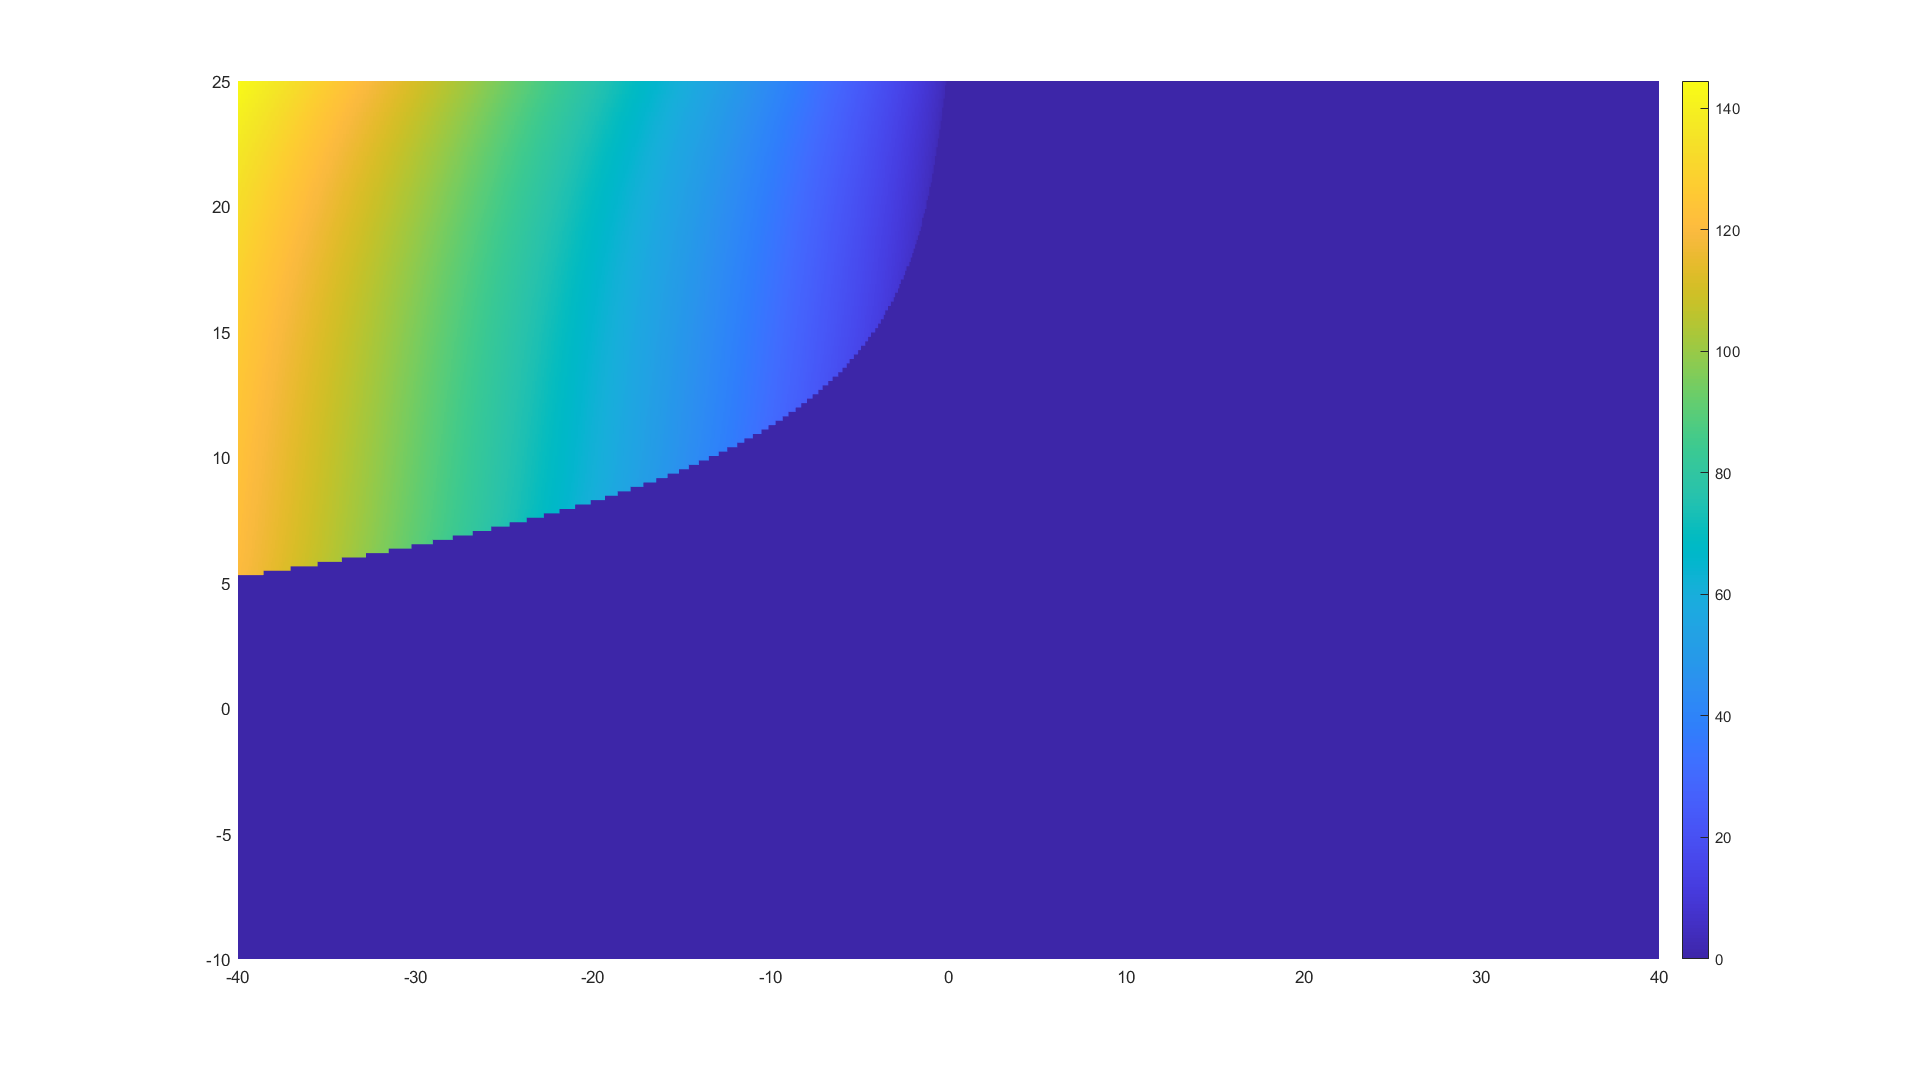

fig = figure('Name','test','NumberTitle','off','units','normalized','outerposition',[0 0 1 1]);    
surf(-delta_mesh, flux_power_mesh_dBm, number_photons_soln_2, 'Linestyle', 'none')
view(0,90)
colorbar